## Software Engineering/Mechatronics 3DX4

DAY CLASS

DURATION OF EXAMINATION: 2.5 Hours

McMaster University Final Examination

Dr. Mark Lawford

April 2018

Special Instructions:

This is an open book exam. You may use your course notes, ny material from Avenue or on the web. You may not post these questions to web forms and solicit help from other students in the class or any other indiviruals. Any online discussion of the exam equestions should take place in the McMaster MECTHRON/SFWRENG 3DX4 Microsoft Teams Exam Channel.  

By submitting this work, I certify that the work represents solely my own independent efforts. I confirm that I am expected to exhibit honesty and use ethical behaviour in all aspects of the learning process.  I confirm that it is my responsibility to understand what constitutes academic dishonesty under the Academic Integrity Policy.

Link:  https://secretariat.mcmaster.ca/app/uploads/Academic-Integrity-Policy-1-1.pdf

clear
% uncomment and enter your name and student number as strings 
% in the variables below
% name="Lastname, Firstname"
% studentNumber="YourStudent#"

**1. Stability** (25 marks)

a) (5 marks) Is the open loop plant

where $G(s)=\frac{s+3}{s^4 + 23 s^3 + 182 s^2 + 580 s + 600}$ stable or unstable? Justify your answer.

% Your code goes here


b) (5 marks) Consider the system shown below  where:


$$D(s)=K\;\mbox{ and } \;G(s)=\frac{s+3}{s^4 + 23 s^3 + 182 s^2 + 580 s + 600}$$


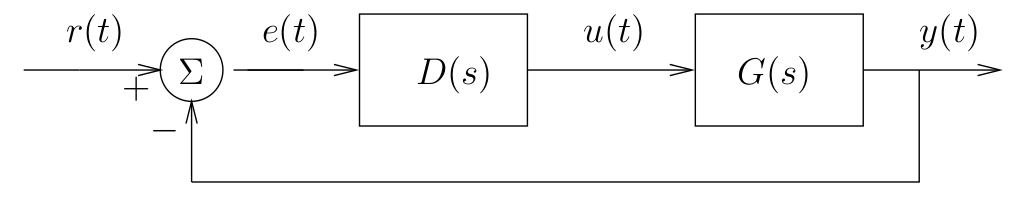

Compute the closed loop transfer function of the system and assign it to the varible $\texttt{G\_clQ1b}$

% Your code goes here
%G_clQ1b=


c) (10 marks) Use matlab to help you find for what values of K is the closed loop system stable.

% Your code goes here


Your final answer for the range of $K$ that the closed loop system is stable goes here:

d) (5 marks) For the value of $K$ when the system is marginally stable (i.e. the closed loop system has pole(s) of multiplicity 1 on the $j\omega$-axis and the other closed loop poles are in the open right half plane, calculate the value of the poles on the$j\omega$-axis. Assign the values to the variable $\texttt{omega\_crossingQ1d}$ . 

% Your code goes here
%omega_crossingQ1d=

**2. Root Locus, Time Response and Controller Design** (25 marks)

Consider the closed loop system:

 in the case when:


$$D(s)=K\;\mbox{ and }\; G(s)=\frac{s+3}{(s+2)(s+5)(s+6)(s+10)}$$


a) (5 marks) Use Matlab to draw the root locus for the control system. You do not need to calculate the exact breakaway/breakin points.

% Your code goes here


b) (5 marks) For K = 430 use Matlab commands to compute the closed loop poles and assign them to the variable $\texttt{poles\_Q2b}$.

% Your code goes here
%poles_Q2b=

Is the closed loop system stable in this case? 

% Uncomment the correct answer
%Q2bClosedLoopStable=true
%Q2bClosedLoopStable=false

Justify your answer in the space below:

Are there any closed loop poles that are close to canceling a system zero? 

What is the damping ratio $\zeta$ of the dominant poles? Use matlab to help you solve for this and assign your answer the variable $\texttt{zeta_Q2b}$

% Your code goes here
%zeta_Q2b=

 Assuming ideal 2nd order behaviour, what do you expect the resulting percent overshoot to be for the system to be?

% Your code goes here
%percentOvershootQ2b=


c) (5 marks) Your manager said that she is happy with % overshoot of your controller design for K = 430, but she would like you to design a PD compensator to cut the settling time in half while keeping the same % overshoot. Assuming ideal 2nd order behaviour, what would be the new location for the dominant poles? Underdamped poles appear in complex conjugate pairs. Assign to the variable $\texttt{s_dQ2}$ the new desired values of both dominant poles. This should be a vector. 

% Your code goes here
%s_dQ2=[ ]


d) (5 marks) Design a PD compensator to place the dominant poles at the location you computed in part (2c).

% Your code goes here



e) (5 marks) Plot the poles and zeros of the closed loop compenstated systems using Matlab:

% Your code goes here


 Now plot both the desired ideal 2nd order step response behaviour and the actual step response of the compensated closed loop system (i.e. $D(s)=K(s+z_c)$ you designed in the previous part) on the same graph.

% Your code goes here


Compute the actual % overshoot and approximate settling time and uncomment and assign those values to the variables $\texttt{actualPOS}$ and $\texttt{actualTs}$ respectively.

% Your code goes here
%actualPOS=
%actualTS=

Does the percent overshoot and settling time appear to correspond to the ideal second order behaviour your manager wanted for the compensated system? Does the closed loop pole zero map you plotted above indicate that this should be the case? Enter your answers in the space below:

**3. Steady State Error** (15 marks)

Assume that


$$G(s)=\frac{s+3}{s^4 + 23 s^3 + 182 s^2 + 580 s + 600}=\frac{s+3}{(s+2)(s+5)(s+6)(s+10)}$$


in the following control system:

a) (5 marks) Assuming the feedback configuration shown above and $D(s) = K$ is chosen so that the closed loop system is stable:

What is the type of the system? Uncomment and set variable $\texttt{n\_type}$ to the type of the system.  

% Your code goes here
%n_type=

Explain your answer in the space below:

 What is its static error constant for a given gain $K$? Put your code below to compute the static error constant and uncomment and  assign it to the variable $\texttt{K\_staticError}$

% Your code goes here
%K_staticError=

 What is the steady state error of the closed loop system in response to a unit step input? Assign your answer the variable $\texttt{e\_stepQ3a}$

% Your code goes here
%e_stepQ3a=


b) (5 marks) The system requires the elimination of the steady state error and robustness with respect to step disturbances. You colleague (who graduated from McMaster) suggests changing the controller from $D(s) = K$ to an integral controller $D(s) = \frac{K}{s}$. 

Is this a good choice? 

% Uncomment the correct answer
%GoodChoice=true
%GoodChoice=false

Is it possible that such a controller would eliminate the steady state error and still have the same % overshoot for an appropriate choice of K? 

% Uncomment the correct answer
%ZeroErrorSamePOSQ3b=true
%ZeroErrorSamePOSQ3b=false

Justify your previous answer with textual explanations and matlab calculations/graphs to support it.


% Your code to help justify your answer goes here


**4. State Space Control** (20 marks)

Assume that the transfer function  of a plant (system you want to control) is given by:


$$G(s)=\frac{s+3}{s^4 + 23 s^3 + 182 s^2 + 580 s + 600}$$


a) (5 marks) Given G(s) what is the controller canonical (phase variable) state space representation of the plant G(s)? Uncomment and assign your answers to the variables below:

% Your code goes here
% A=
% B=
% C=
% D=

Verify that your state space represetntation does in fact correspond to the transfer function $G(s)=\frac{s+3}{s^4 + 23 s^3 + 182 s^2 + 580 s + 600}$ using Matlab to assign your transfer function computed from your statespace represtentation to the variable $\texttt{G_stateSpace}$

% Your code goes here
%G_stateSpace=

b) (5 marks) A state feedback control $u = -Kx$ is to be used to:

• place one of the closed loop poles is to be placed at $s = -3$ to exactly cancel the system zero,

• place the dominant poles at $s = -5.4 \pm j12.2$ to get the desired % overshoot and settling time, and

• place the final pole at $s = -54$ so it won’t interfere.

What would the desired characteristic equation of the designed closed loop system be? Create a symbolic polynomial in $s$ and assign it to the variable $\texttt{d_desiredQ4}$

% Your code goes here
%d_desiredQ4=

c) (5 marks) Use Matlab to compute a state feedback control matrix $K$ to place the poles at the desired locations. Assign your answer to th variable $\texttt{K\_Q4c}$

% Your code goes here
%K_Q4c=


d) (5 marks) Is the state space representation from part (4a) observable so that we can implement our state feedback controller given our current sensor outputs? Justify your answer with the help of Matlab. Assign the correct truth value to the variable $\texttt{Q4aObservable}$ below after you use Matlab

% Your code goes here
%
%
% Uncomment the correct answer
%Q4aOservable=true
%Q4aOservable=false

**5. Bode Plot Margins, Bandwidth & Digital Control** (15 marks)

Consider the closed loop system:

 in the case when:

$D(s)=K=430$ and


$$G(s)=\frac{s+3}{s^4 + 23 s^3 + 182 s^2 + 580 s + 600}=\frac{s+3}{(s+2)(s+5)(s+6)(s+10)}$$


a) (5 marks) Use Matlab to plot the open loop bode plot of $D(s)G(s)$:

% Your code goes here


What is the gain margin $\texttt{Gm}$ for the system above system? 

% Your code goes here
%Gm=

Consider the statement:

    The gain margin you gave above is given in dB. 

Uncomment the correct answer:

% Uncomment the correct answer
%GmIsIndB=true
%GmIsIndB=false

What is the phase margin $\texttt{Pm}$ for the system above? 

% Your code goes here
%Pm=

Consider the statement:

    The phase margin you gave above is given in degrees. 

Uncomment the correct answer:

% Uncomment the correct answer
% PmIsInDegrees=true
% PmIsInDegrees=false

Use Matlab to and your answer for the gain margin to compute value $K^*$, the value of $K$ when the system would no longer be strictly stable. Assign your answer the the variable $\texttt{K\_starQ5}$ 

% Your code goes here
%K_starQ5=


Use matlab to check that when $D(s)=K^*$ the closed loop system is only marginally stable:

% Your code here:


b) (5 marks) Plot the Bode plot for the closed loop system transfer function with D(s) = K = 430 

% Your code here:


Find the bandwidth of the closed loop system using Matlab and asign it to the variable $\texttt{omega\_BM}$:

% Your code here
%omega_BW=

c) (5 marks) What is the formula to compute the Zero Order Hold Equivalent of the plant $G(s)$?  Put it in the space below:

For a sampling rate of 10 Hz, use Matlab to find the Zero Order Hold Equivalent of 


$$G(s)=\frac{s+3}{s^4 + 23 s^3 + 182 s^2 + 580 s + 600}=\frac{s+3}{(s+2)(s+5)(s+6)(s+10)}$$


and assign it to the variable $\texttt{G\_zoh}$

% Your code goes here
%G_zoh=

What are the pole locates of the open loop zero order hold equivalent?

% Your code goes here
%poles_Gzoh=

Which one of these poles if the digital pole corresponding to $s = -6$ pole of $G(s)$ (i.e. where is the $s=-6$ pole located in the z-plane? Assign your answer to the variable $\texttt{minus6PoleG\_zoh}$.

% Your code goes here
%minus6PoleG_zoh=
